# **Primi passi con MATLAB**

**Obiettivo.** Crash intro per essere in grado di caricare dei dati, plottarli e fittarli. I dettagli seguiranno con calma.

## PULIZIA / COMMENTI

Purtroppo i Livescript hanno la tendenza a diventare lenti quanto contengono molti dati e grafici, e quando la RAM si riempie di variabili, magari non più usate. E' buona prassi iniziare con... 

% Qualsiasi cosa segua un % e` un commento e non viene eseguito
% se non mettete un ; alla fine del comando tipicamente viene mostrato
% qualcosa nell'output (ossia qui a destra in un LiveScript).

clear all;  % Elimina tutte le variabili dal Workspace
close all;  % Chiude tutte le finestre

Inoltre cliccando col tasto destro nella colonna dell'ouput è possibile eliminare tutti gli output.

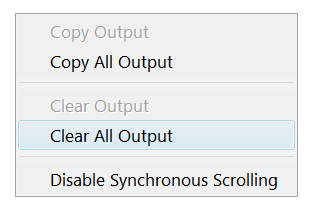

## CARICARE I DATI DA FILE

Negli script "normali" (quelli che terminano per `.m`), Matlab automaticamente imposta la directory dove è salvato lo script come directory di lavoro. Questo non succede con i Livescript, ma a volte è comodo poterlo fare comunque, grazie al seguente comando:

cd(fileparts(matlab.desktop.editor.getActiveFilename));

Per caricare i dati da un file (provate ad aprirlo con un editor di testo per vedere come e` fatto in caso di dubbi) esistono svariati comandi in MATLAB. Fra questi consigliamo `readmatrix`: semplice e solido. Prima di caricare il file, è utile vedere come è fatto... in questo caso abbiamo un ASCII con numeri separati da virgola. File di questo tipo vengono spesso chiamati `CSV = Comma Separated Value`.

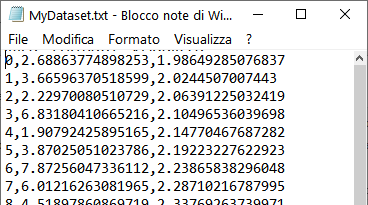

data = readmatrix("MyDataset.txt")

data =          0    2.6886    1.9865
    1.0000    3.6660    2.0245
    2.0000    2.2297    2.0639
    3.0000    6.8318    2.1050
    4.0000    1.9079    2.1477
    5.0000    3.8703    2.1922
    6.0000    7.8726    2.2387
    7.0000    6.0122    2.2871
    8.0000    4.5190    2.3377
    9.0000    4.5955    2.3906


Fra le n altre opzioni disponibili per caricare i files, gli studenti a volte apprezzano anche `readtable`

tbl = readtable("Misura_001.txt",NumHeaderLines=4);

% Rinominiamo subito le variabili
tbl.Properties.VariableNames = ["timestamp" "Ch1" "Ch2"]

tbl = 8000×3 table
         timestamp            Ch1         Ch2   
    ____________________    ________    ________

    21-Sep-2023 09:52:46    -0.80162    -0.72451
    21-Sep-2023 09:52:46    -0.80263    -0.72485
    21-Sep-2023 09:52:46    -0.80028    -0.72822
    21-Sep-2023 09:52:46    -0.79894    -0.72889
    21-Sep-2023 09:52:46    -0.79491    -0.72417
    21-Sep-2023 09:52:46    -0.79558     -0.7299
    21-Sep-2023 09:52:46    -0.79458    -0.72956
    21-Sep-2023 09:52:46    -0.79726    -0.73024
    21-Sep-2023 09:52:46    -0.79558    -0.73428
    21-Sep-2023 09:52:46    -0.78854    -0.72822
    21-Sep-2023 09:52:46    -0.78887    -0.73024
    21-Sep-2023 09:52:46    -0.78854    -0.72889
    21-Sep-2023 09:52:46    -0.78619    -0.72956
    21-Sep-2023 09:52:46    -0.78653    -0.73192
    21-Sep-2023 09:52:46    -0.78921     -0.7363
    21-Sep-2023 09:52:46    -0.78485    -0.73

% l'accesso alle singole colonne di dati è banale
tbl.Ch1

ans =    -0.8016
   -0.8026
   -0.8003
   -0.7989
   -0.7949
   -0.7956
   -0.7946
   -0.7973
   -0.7956
   -0.7885


Un ulteriore vantaggio delle tabelle è che possono leggere correttamente i `timestamp` (in questo caso la prima colonna) che saranno contenuti nei dati di tipo `waveform`. Sicuramente in questo caso è utile considerare il formato del file, che contiene un header con varie informazioni, per esempio sul tempo di inizio della misura `t0` e sull'intervallo di campionamento `dt`

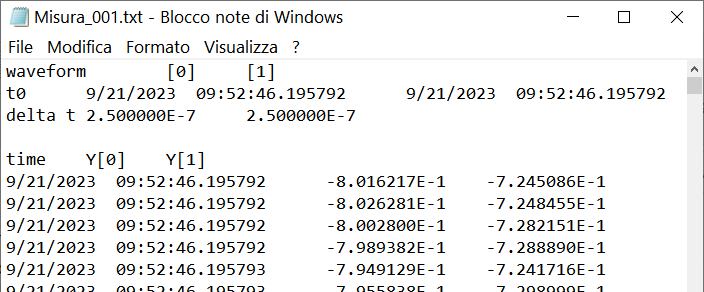

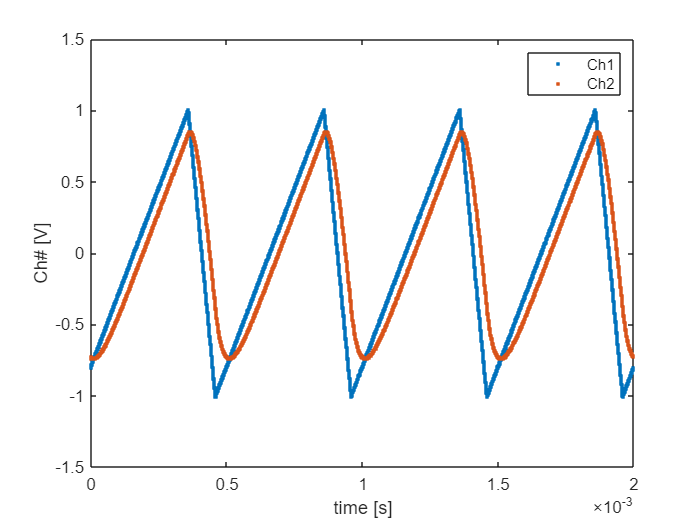

t0 = tbl.timestamp(1);                 % Recuperiamo il tempo di inizio della misiura
tbl.t = seconds(tbl.timestamp-t0);     % Convertiamo il tempo passato in unità gestibili
tbl.timestamp = [];                    % Eliminiamo la colonna timestamp
plot(tbl.t, [tbl.Ch1 tbl.Ch2],'.');
legend("Ch1","Ch2");
xlabel("time [s]");
ylabel("Ch# [V]");

## OTTENERE INFO SU COMANDI E VARIABILI

Qualche comando diagnostico utile per ottenere informazioni su un comando...

help readmatrix     % Documentazione testuale

 readmatrix Create a matrix by reading from a file.
 
     Use the readmatrix function to create a homogeneous array by reading
     column-oriented data from a file. readmatrix automatically determines
     the file format from its extension.
 
     A = readmatrix(FILENAME) creates a homogeneous array by reading from a
         file.
     FILENAME can be one of these:
 
         - For local files, FILENAME can be an absolute path that contains
           a filename and file extension. FILENAME can also be a relative
           path to the current directory or to a directory on the MATLAB
           path. For example, to import a file on the MATLAB path:
 
              A = readmatrix("matrix.xls");
 
         - For files from an Internet URL or stored at a remote location,
           FILENAME must be a full path using a Uniform Resource Locator
           (URL). For example, to import a remote file from Amazon S3,
   

doc readmatrix      % Documentazione estesa

Oppure su una variabile: `data` e` una matrice di 101 righe per 3 colonne

whos data

  Name        Size            Bytes  Class     Attributes

  data      101x3              2424  double              



whos tbl

  Name         Size             Bytes  Class    Attributes

  tbl       8000x3             193733  table              



Utile ricordare che il formato di stampa può essere cambiato

format short
aa = pi

aa = 3.1416

format long
aa

aa =    3.141592653589793


format hex
aa

aa =    400921fb54442d18


format short

## GESTIONE BASIC DI DATI MATRICIALI

Facciamo un minimo di pratica con un dato di tipo matriciale. MATLAB offre una sintassi particolarmente diretta per le matrici

% Come ottenere le dimensioni di una variabile
dimensione = size(data)

dimensione =    101     3


% Il risultato e` qui a sua volta un vettore 1x2, quindi per ottenere le
% singole dimensioni possiamo fare
nrighe   = dimensione(1)

nrighe = 101

ncolonne = dimensione(2)

ncolonne = 3


% Esempi di come si puo` accedere a singoli elementi o sottomatrici
aa = data(1,2)

aa = 2.6886

bb = data(1:5,1)

bb =      0
     1
     2
     3
     4


cc = data([1 2 3 4 50],1)

cc =      0
     1
     2
     3
    49


% notare la keyword "end" che qui equivale a scrivere 101... al posto di
% "1:end" potete anche scrivere semplicemente ":"
dd = data(1:end,2)

dd =     2.6886
    3.6660
    2.2297
    6.8318
    1.9079
    3.8703
    7.8726
    6.0122
    4.5190
    4.5955



% A questo punto e` chiaro come estrarre le singole colonne del dato
xv = data(:,1)

xv =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


yv = data(:,2);
ev = data(:,3);

Finora abbiamo sfruttato una matrice caricata da file tramite `readmatrix`. Chiaramente  possiamo anche definirne alcune nel codice. Vedremo qualche ulteriore esempio in seguito, qui vediamo come si possono definire matrici elemento per elemento.

vettore = [1,2,5]

vettore =      1     2     5


matrice = [1 3 5; ... % i tre punti servono a continuare
           0 7 9; ... % un comando
           5 7 7]     % su piu` righe

matrice =      1     3     5
     0     7     9
     5     7     7



% Qualche esempio di prodotto riga per colonna
vettore*matrice

ans =     26    52    58


matrice*(vettore')

ans =     32
    59
    54


scalar = vettore*vettore'

scalar = 30

tensor = (vettore')*vettore

tensor =      1     2     5
     2     4    10
     5    10    25



% Posso anche scrivere cose del genere, dove genero una matrice con due
% vettori riga noti (in questo caso due copie dello stesso vettore)
[vettore; vettore]

ans =      1     2     5
     1     2     5


Lo standard in MATLAB è fare i prodotti riga per colonna ma si può anche obbligarlo a fare operazioni ELEMENTO PER ELEMENTO aggiungendo un . prima dell'operatore. Questo e` necessario per */^ mentre ovviamente è inutile per +-

matrice

matrice =      1     3     5
     0     7     9
     5     7     7


% Operazioni matriciali
matrice*matrice

ans =     26    59    67
    45   112   126
    40   113   137


matrice^2

ans =     26    59    67
    45   112   126
    40   113   137


% Operazioni elemento per elemento
matrice.*matrice

ans =      1     9    25
     0    49    81
    25    49    49


matrice.^2

ans =      1     9    25
     0    49    81
    25    49    49


Ovviamente MATLAB supporta tutte le operazioni che vi potete immaginare con le matrici, ma ora ci porterebbe fuori topic.

% Determinante
det(matrice)

ans = -54.0000

% Matrice inversa
inv(matrice)*matrice

ans =     1.0000    0.0000    0.0000
    0.0000    1.0000   -0.0000
         0   -0.0000    1.0000


Infine... e` utile sapere come generare alcuni vettori standard con spaziatura costante

vettore1 = [1 2 3 4 5]

vettore1 =      1     2     3     4     5


vettore2 = 1:5

vettore2 =      1     2     3     4     5


vettore3 = (1:0.2:5)

vettore3 =     1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000    4.2000    4.4000    4.6000    4.8000    5.0000


vettore4 = linspace(1,5,11)

vettore4 =     1.0000    1.4000    1.8000    2.2000    2.6000    3.0000    3.4000    3.8000    4.2000    4.6000    5.0000


Caso interessante, esponenziale di matrici.

II = [0 -1; 1 0];
phi = 0.234;
expm(II*phi)

ans =     0.9727   -0.2319
    0.2319    0.9727


cos(phi)

ans = 0.9727

sin(phi)

ans = 0.2319

## PLOT DEI DATI

Torniamo all'obiettivo: abbiamo caricato dei dati, abbiamo estratto le x, le y e gli errori salvati. Ora vogliamo plottarli

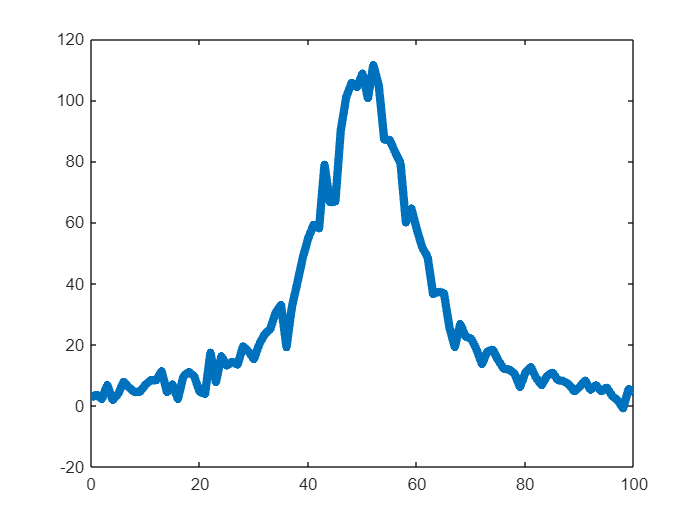

% 1. Plot standard
plot(xv,yv,"-",LineWidth=5);

% (plot a pallini vuoti) oppure '.' (plot a punti/cerchi pieni).
% LineWidth (che abbiamo impostato a 5) e` una di svariate opzioni possibili.
% per info provare...
help plot

 plot   Linear plot. 
    plot(X,Y) plots vector Y versus vector X. If X or Y is a matrix,
    then the vector is plotted versus the rows or columns of the matrix,
    whichever line up.  If X is a scalar and Y is a vector, disconnected
    line objects are created and plotted as discrete points vertically at
    X.
 
    plot(Y) plots the columns of Y versus their index.
    If Y is complex, plot(Y) is equivalent to plot(real(Y),imag(Y)).
    In all other uses of plot, the imaginary part is ignored.
 
    Various line types, plot symbols and colors may be obtained with
    plot(X,Y,S) where S is a character string made from one element
    from any or all the following 3 columns:
 
           b     blue          .     point              -     solid
           g     green         o     circle             :     dotted
           r     red           x     x-mark         

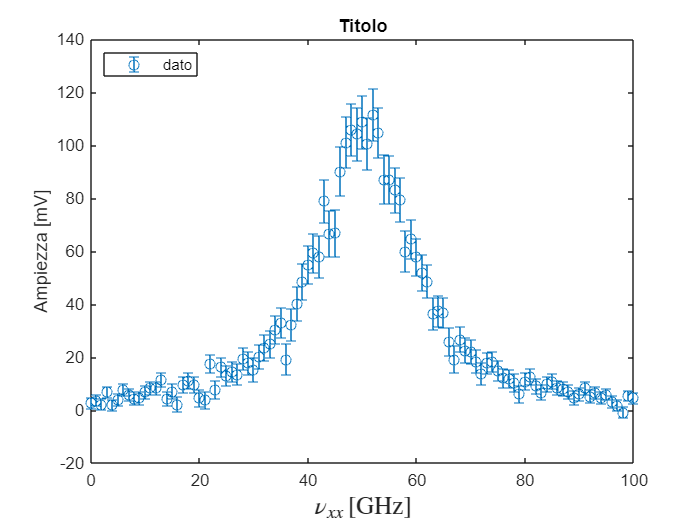


% 2. Plot con errori
errorbar(xv,yv,ev,'o');
xlabel("$\nu_{xx}\,{\rm[GHz]}$","Interpreter","latex",FontSize=15);
ylabel("Ampiezza [mV]");
title("Titolo");
legend("dato",Location="NW");

## FIT DEI DATI - BASIC

Fit preliminare in cui usiamo i pesi statistici. Una (fra tante) funzioni di minimizzazione del chi quadro e` `nlinfit` (= non-linear fit, ovviamente). Qui sotto la usiamo in maniera "basic", senza ricavare gli errori di fit. Vedremo Mar 27 che e` possibile ottenere anche il valore del chi quadro ridotto e gli errori. Vedremo anche come si declina l'annosa questione `absolute_sigma` in MATLAB.

% Parametri di partenza (sceglieteli bene! e` fondamentale)
pp0 = [100 40 15];

% Nella sua versione piu` basic, il fit si fa come segue
pp = nlinfit(xv,yv,@fitfunc,pp0,Weights=ev.^-2)'

pp =   108.4216
   50.5217
    9.5290


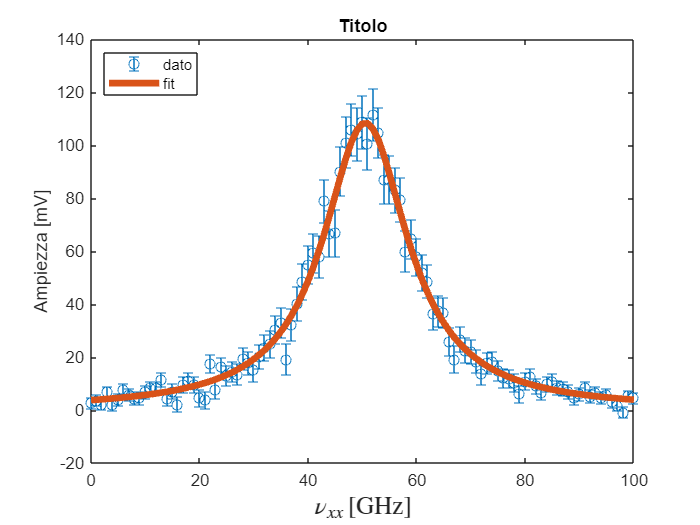


% Plottiamolo in cima al dato
hold on;    % questo dice a MATLAB di continuare a disegnare sullo stesso plot
plot(xv,fitfunc(pp,xv),LineWidth=4);
hold off;   % e questo gli dice di smettere e tornare alla modalita` standard
            % i.e. ogni plot finisce su un grafico nuovo

legend("dato","fit",Location="NW");

Per avere informazioni sulla funzione di fit al solito possiamo fare...

help nlinfit

 nlinfit Nonlinear least-squares regression.
    BETA = nlinfit(X,Y,MODELFUN,BETA0) estimates the coefficients of a
    nonlinear regression function, using least squares estimation.  Y is a
    vector of response (dependent variable) values.  Typically, X is a
    design matrix of predictor (independent variable) values, with one row
    for each value in Y and one column for each coefficient.  However, X
    may be any array that MODELFUN is prepared to accept.  MODELFUN is a
    function, specified using @, that accepts two arguments, a coefficient
    vector and the array X, and returns a vector of fitted Y values.  BETA0
    is a vector containing initial values for the coefficients.
 
    [BETA,R,J,COVB,MSE] = nlinfit(X,Y,MODELFUN,BETA0) returns the fitted
    coefficients BETA, the residuals R, the Jacobian J of MODELFUN, the
    estimated covariance matrix COVB for the fitted coefficients, and an
    estimate MSE of the varianc

## FIT DEI DATI - COMPLETO

Qui ripetiamo la procedura di fit, gestendo anche la questione degli errori presi in senso relativo o assoluto.

% Parametri di partenza (sceglieteli bene! e` fondamentale)
pp0 = [100 40 15];

% Chiediamo un risultato piu "completo" a MATLAB: vedere help
[pp,~,~,covb,chi2n] = nlinfit(xv,yv,@fitfunc,pp0,Weights=ev.^-2);
% covb contiene la matrice di covarianza "taroccata", riscalando gli errori
% quanto basta per portare il chi2n normalizzato a 1. Notare: la variabile
% chi2n qui sopra contiene in chi quadro normalizzato VERO (riscalato
% sarebbe inutile... e` 1)

% SE vogliamo prendere gli errori in maniera assoluta, dobbiamo
% semplicemente riportare covb al suo valore originario facendo
covb = covb/chi2n;
% SE vogliamo prendere gli errori in maniera relativa, semplicemente NON va
% riscalata cobv come nell'istruzione qui sopra. 

% Calcolo del vettore delle incertezze di fit e correlazione
epp = sqrt(diag(covb));
corr = (covb./epp)'./epp;

% Stampa dei risultati del fit (NB poi nelle relazioni mettiamo il numero
% di cifre significative giusto!)
fprintf("chi2n = %.6f\n",chi2n);

chi2n = 0.740176


for ii=1:length(pp)
    fprintf("pp(%d) = %7.3f +/- %7.3f\n",ii,pp(ii),epp(ii));    
end

pp(1) = 108.422 +/-   3.275
pp(2) =  50.522 +/-   0.234
pp(3) =   9.529 +/-   0.270


## CREARE UN PDF (VETTORIALE) DEL GRAFICO

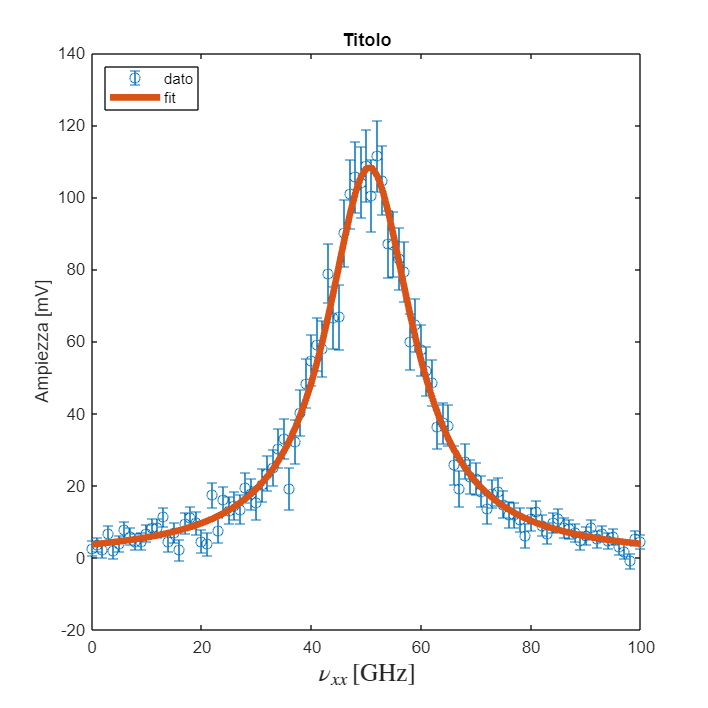

 nlinfit Nonlinear least-squares regression.
    BETA = nlinfit(X,Y,MODELFUN,BETA0) estimates the coefficients of a
    nonlinear regression function, using least squares estimation.  Y is a
    vector of response (dependent variable) values.  Typically, X is a
    design matrix of predictor (independent variable) values, with one row
    for each value in Y and one column for each coefficient.  However, X
    may be any array that MODELFUN is prepared to accept.  MODELFUN is a
    function, specified using @, that accepts two arguments, a coefficient
    vector and the array X, and returns a vector of fitted Y values.  BETA0
    is a vector containing initial values for the coefficients.
 
    [BETA,R,J,COVB,MSE] = nlinfit(X,Y,MODELFUN,BETA0) returns the fitted
    coefficients BETA, the residuals R, the Jacobian J of MODELFUN, the
    estimated covariance matrix COVB for the fitted coefficients, and an
    estimate MSE of the varianc

myfig = gcf; % get current figure
myfig.Position(3:4) = [600 600];
exportgraphics(gcf,"Test.pdf",ContentType="vector");

## **OTTENERE DISTRIBUZIONE DI UN DATASET **

Vediamo come si crea un istogramma e un diagramma a barre. 

tbl = readtable("Misura_002.txt",NumHeaderLines=4);

% Rinominiamo subito le variabili
tbl.Properties.VariableNames = ["timestamp" "Ch1" "Ch2"]

tbl = 8000×3 table
         timestamp             Ch1            Ch2    
    ____________________    __________    ___________

    21-Sep-2023 09:52:58    -0.0049428     -0.0020742
    21-Sep-2023 09:52:58     0.0014306     -0.0010633
    21-Sep-2023 09:52:58    -0.0012529    -5.2457e-05
    21-Sep-2023 09:52:58     0.0010952    -5.2457e-05
    21-Sep-2023 09:52:58     0.0014306    -0.00072637
    21-Sep-2023 09:52:58     0.0034433     0.00062146
    21-Sep-2023 09:52:58    8.8839e-05    -5.2457e-05
    21-Sep-2023 09:52:58    0.00075973     -0.0014003
    21-Sep-2023 09:52:58     0.0014306      0.0019693
    21-Sep-2023 09:52:58    -0.0012529     0.00062146
    21-Sep-2023 09:52:58    -0.0015884    -0.00072637
    21-Sep-2023 09:52:58    -0.0025947    -0.00038941
    21-Sep-2023 09:52:58     0.0010952      0.0002845
    21-Sep-2023 09:52:58    -0.0019238     0.00095841
    21-Sep-202

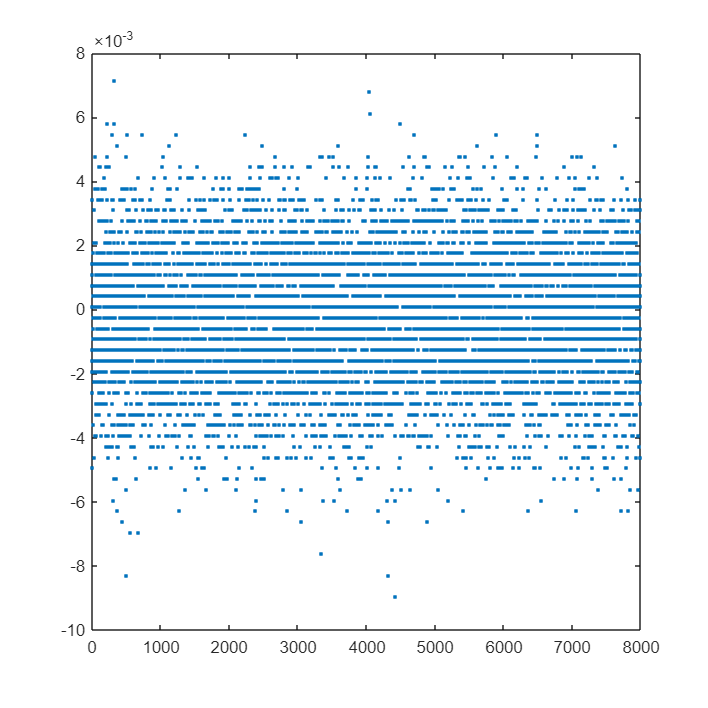

plot(tbl.Ch1,'.')

In generale si può estrarre un istogramma con la seguente operazione, in cui lasciamo a MATLAB scegliere come fare il binning

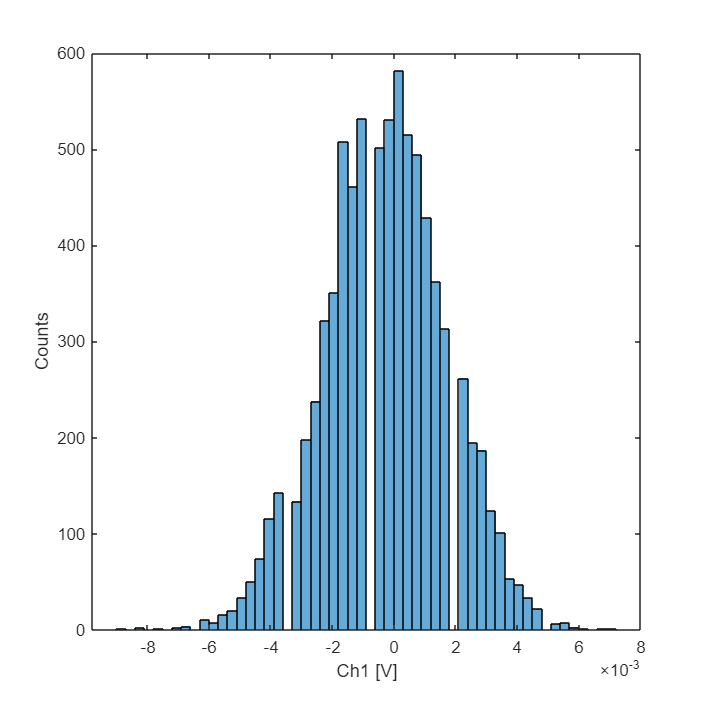

histogram(tbl.Ch1);
xlabel("Ch1 [V]");
ylabel("Counts");

Dato che in questo caso abbiamo degli specifici livelli discreti in realtà potremmo fare di meglio e contare le occorrenze di ogni singolo valore non ripetuto che compare nella sequenza. Quindi vorremmo ricostruire `dx` e un valore minimo

% Prendiamo la minima distanza fra i valori unici della sequenza (ordinati)
dx = min(diff(unique(tbl.Ch1)))

dx = 3.3544e-04

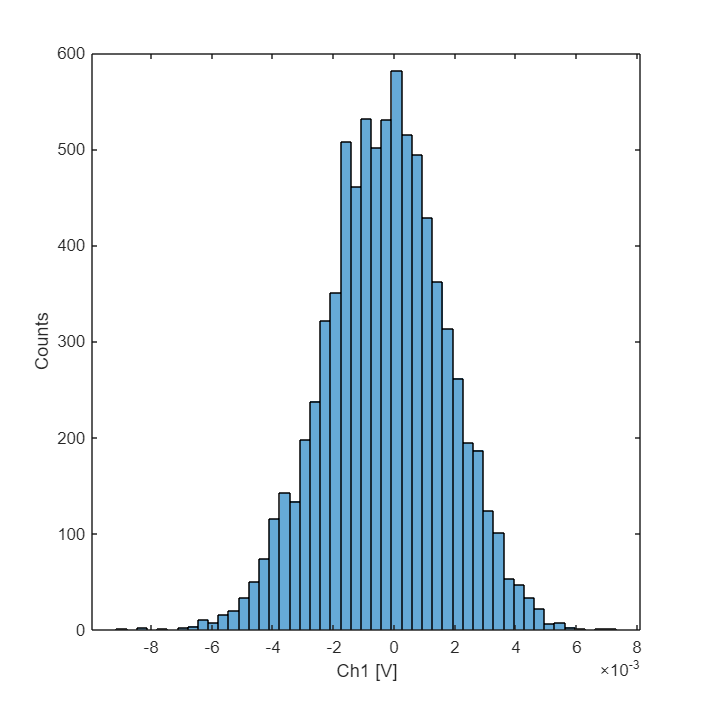

% Bordi dei bins
bines = (min(tbl.Ch1)-dx/2):dx:(max(tbl.Ch1)+dx/2);
bins  = min(tbl.Ch1):dx:max(tbl.Ch1);
histogram(tbl.Ch1,BinEdges = bines);
xlabel("Ch1 [V]");
ylabel("Counts");

A questo punto proviamo a fare un fit gaussiano. In questo caso prenderemo degli errori Poissoniani e togliamo gli eventuali bin con zero conteggi (nelle code possono capitare)

[cv,edges] = histcounts(tbl.Ch1,BinEdges = bines);
% Eliminiamo gli zeri
ii = find(cv>0);
cv = cv(ii);
xv = bins(ii);
ev = sqrt(cv); % errore poissoniano

%errorbar(vv,cv,ev,'o');

E a questo punto è possibile procedere con la solita procedura di fit. Per l'occasione mostriamo come sia possibile definire la funzione di fit usando una **"funzione anonima"**.

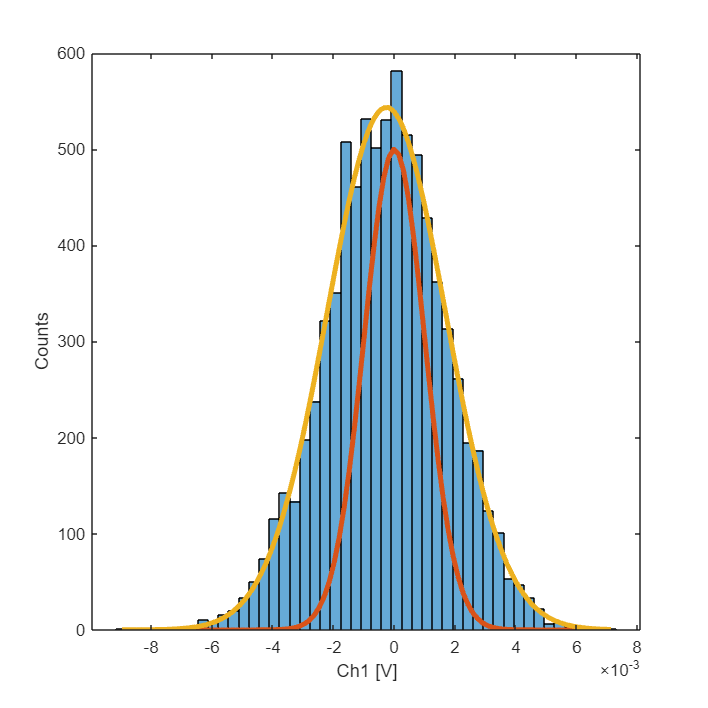

gaussfit = @(p,x)(p(1)*exp(-(x-p(2)).^2/(2*p(3)^2)));
p0 = [500 0 1e-3];
[pp,~,~,covb,chi2n] = nlinfit(xv,cv,gaussfit,p0,Weights=ev.^-2);
covb = covb/chi2n;
epp = sqrt(diag(covb));

% Possiamo anche infittire le x per avere una funzione di fit più smooth
vv2 = linspace(min(xv),max(xv),100);
hold on; 
plot(vv2,gaussfit(p0,vv2),LineWidth=3); 
plot(vv2,gaussfit(pp,vv2),LineWidth=3); 
hold off;


fprintf("chi2n = %f\n",chi2n);

chi2n = 1.607835


function yy = fitfunc(pp,xx)
    % Notare: usiamo "./" (al posto di un banale "/") e ".^" (al posto di "^")
    % perche' xx e` in generale un vettore quindi se usassimo ^2 MATLAB 
    % cercherebbe di fare il quadrato matriciale e dato che xx non e` una matrice 
    % quadrata in genere, si lamenterebbe che le dimensioni non gli tornano. 
    % Qui semmai vogliamo fare delle operazioni elemento per elemneto.
    yy = pp(1)*pp(3)^2 ./ ( (xx-pp(2)).^2 + pp(3)^2 );
end